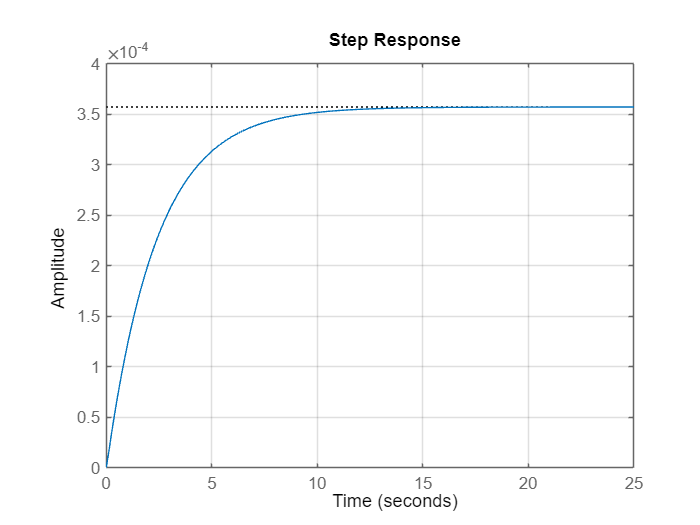

clc
clear all

m = 100;    %Masa [kg]
c = 6700; %n/(m/s)
k = 2800;   %

H = tf(1,[m c k]);

figure
stepplot(H);
grid on

stepinfo(H)

ans = struct with fields:
         RiseTime: 5.2243
    TransientTime: 9.3174
     SettlingTime: 9.3174
      SettlingMin: 3.2282e-04
      SettlingMax: 3.5713e-04
        Overshoot: 0
       Undershoot: 0
             Peak: 3.5713e-04
         PeakTime: 25.0763


sadada

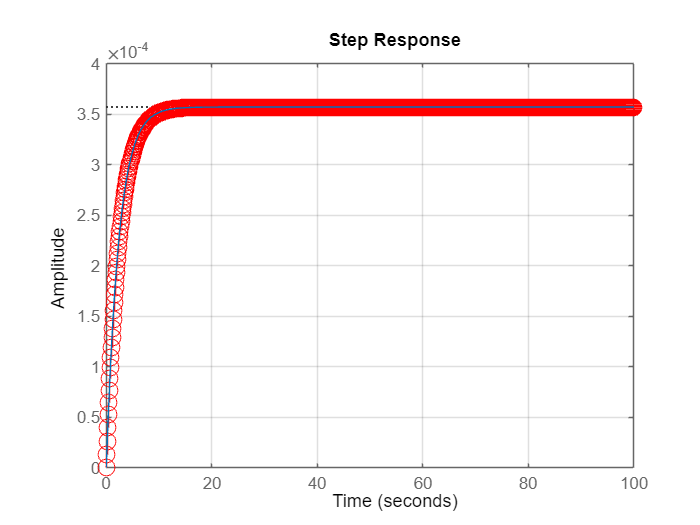

ti = 0; %Tiempo inicial
tf = 100; %Tiempo final
Ts = 0.1;
t = ti:Ts:tf;
T_k = zeros(1,length(t));

T_k1 = 0;
T_k2 = 0;
F = 1;

for i=2:length(t)
    T_k(i) = (F*(Ts^2) + T_k1*(200+6700*Ts) - 100*T_k2)/(100+6700*Ts+(Ts^2)*2800);
    T_k2 = T_k1;
    T_k1 = T_k(i);
    
end

figure
plot(t,T_k,'-O','color','r','MarkerSize',10);
hold on
stairs(t,T_k,'color','r');
step(H);
grid on
axis([0 tf 0 4e-4])